# Practice Thresholding Grayscale Images

- global binarization

- adaptive binarization

- and multilevel thresholding

clc
clear
close all

## Otsu's method for grayscale binarization

The default behavior for the `graythresh` and `imbinarize` functions is to choose a threshold value using Otsu's method. This method works well if the object you are trying to segment has pixels with intensity values that are very different from the surrounding background. For instance, the crack in image `00187.jpg` from the concrete dataset.

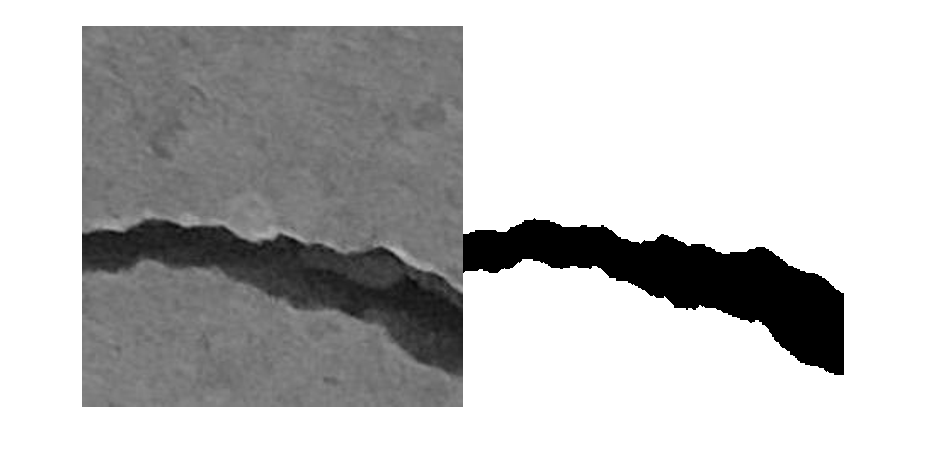

img187 = im2gray(imread("00187.jpg"));
BW1 = imbinarize(img187);
montage({img187,BW1})

This binary image now is called a mask, beause you can overlay it on to the image and mask out the false or black region.

we are intrested in crack we should use lagical operation 'not' to turn pixels of the crack true, and later on keep this part of th image.maskedIMG = img187;

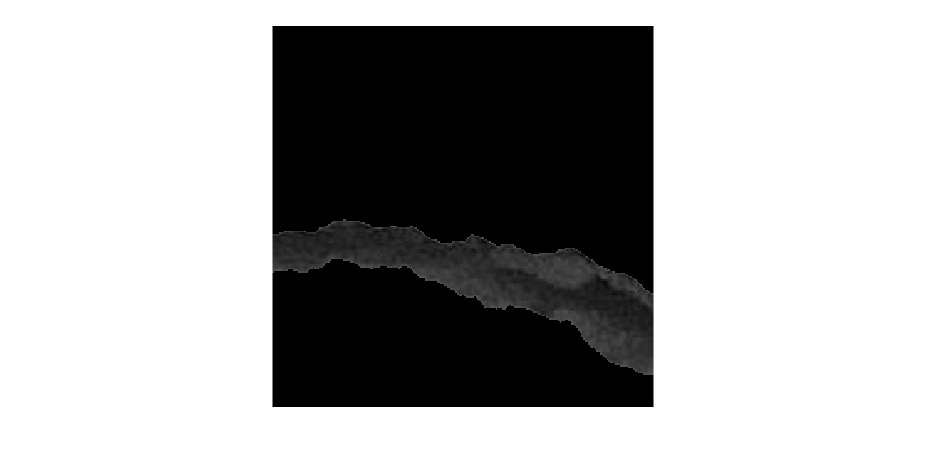

maskedIMG = img187;
maskedIMG(BW1) = 0;
imshow(maskedIMG)

However, if the object you want to segment is small or is only slightly different in intensity from the background, Otsu's method may choose a threshold value that doesn't isolate the intended region. For instance, image `00051.jpg`.

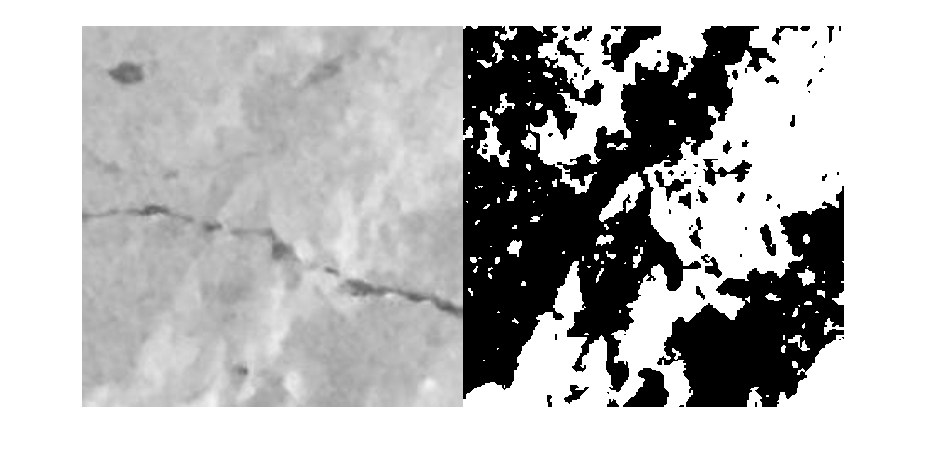

img051 = im2gray(imread("00051.jpg"));
BW2 = imbinarize(img051);
montage({img051,BW2})

## Setting a manual threshold

You can set your own threshold value manually using the second input to the `imbinarize` function. Here we've added a slider control for easy testing. Use this section to experiment with different images and values.

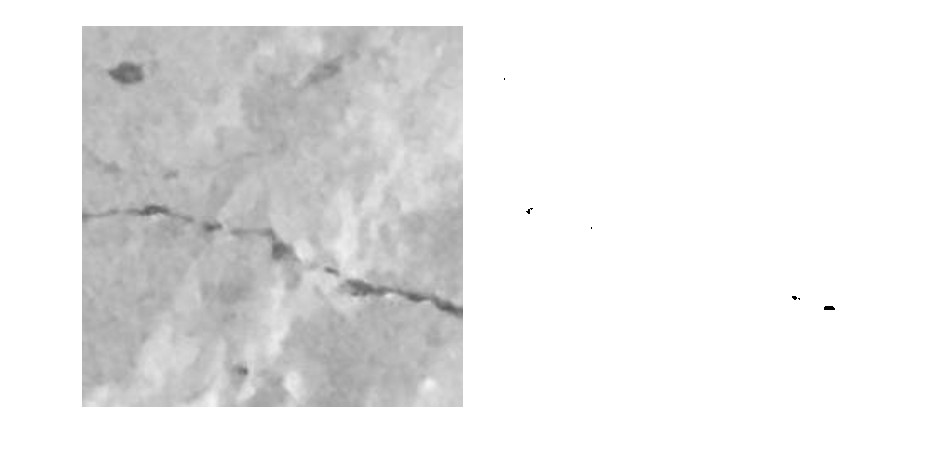

img = im2gray(imread("00051.jpg"));
BW = imbinarize(img,0.4);
montage({img,BW})

Don't worry if you can't achieve a "perfect" mask even with a manual threshold value. Later, you’ll learn techniques to adjust an initial binarization result to better match the object.

## Adaptive binarization

Use *adaptive binarization* in cases where your image has uneven illumination that causes the objects you want to segment to have different intensities depending on their location. Use the image of rice below to segment all of the light grains from the dark background.

There are two additional input options available to adaptive binarization:

- *Foreground Polarity*: Options are `Bright` (default) or `Dark`. Set to "bright" if your object is brighter than the background, and "dark" if it is darker than the background.

- *Sensitivity*: A value from `0` to `1`, with a default of `0.5`. A high sensitivity value leads to thresholding more pixels as foreground, at the risk of including some background pixels.

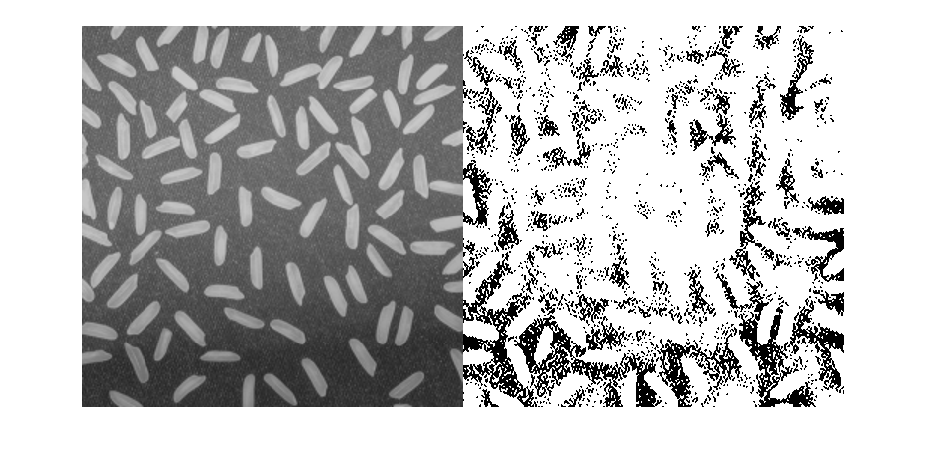

img = imread("rice.png");
BW = imbinarize(img,"adaptive",...
    "ForegroundPolarity","bright",...
    "Sensitivity",0.835);
montage({img,BW})

## Multilevel thresholding

Some applications require isolating multiple regions in the same image. Therefore, instead of a binary mask (with just true or false values), you can label each pixel with an integer and have as many values as needed. Use the slider in the code below to adjust the number of thresholds you would like to make. The number of resulting labels will be this number plus one. By default, `multithresh` also uses Otsu's method to find the threshold values.

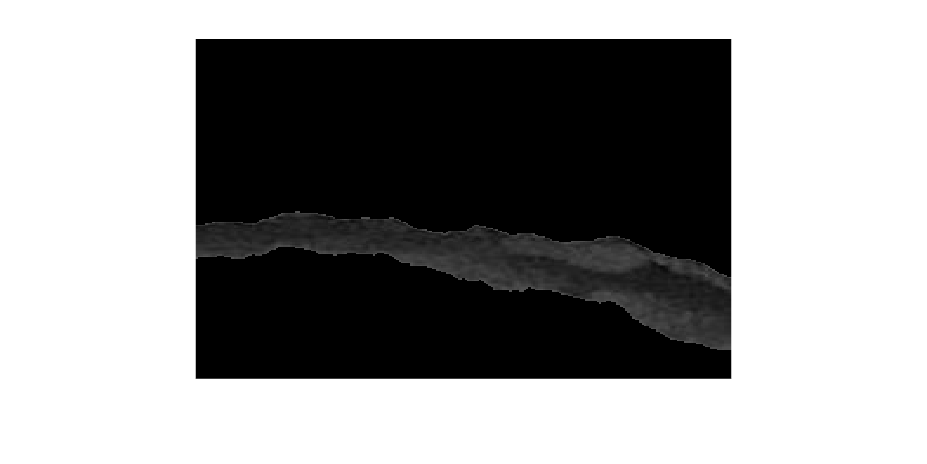

img = imread("armxray.png");
threshValues = multithresh(img,6);
labels = imquantize(img,threshValues);
labelsColor = label2rgb(labels);
montage({img,labelsColor})

## Setting a manual multilevel threshold

Just like with binarization, you can use your own values for multilevel thresholding. Play with the slider controls below to see if you can find better threshold values than Otsu's method for segmenting the four regions of: metal, bone, tissue, and background. Use the Image Viewer App to explore possible intensity values.

img = imread("armxray.png");

threshValues = [26,...
                79,...
                241];
threshValues

threshValues =     26    79   241


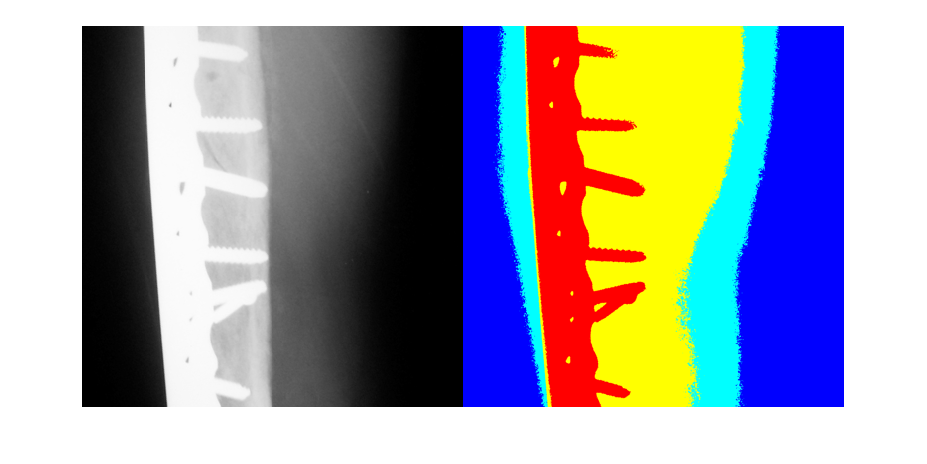

labels = imquantize(img,threshValues);
labelsColor = label2rgb(labels);
montage({img,labelsColor})